# Chapter 17 Problem 27

## Problem Statement

The disk in problem 17.27 is rolling without slipping. Use the Matlab symbolic toolbox to determine the velocity of an arbitrary point E on the rim as a function of $\theta$. Plot the magnitude of the velocity as a function of $\theta$.

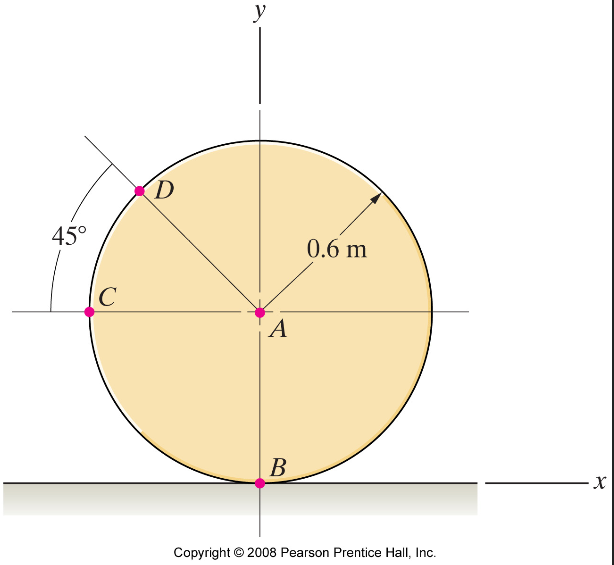

Define symbolic variables:

syms theta omega r

The equation for point E is


$$\bar{v}_E=\bar{v}_B+\bar{\omega}\times \bar{r}_{E/B}$$


vE = [0;0;0]+cross([0;0;omega],r*[cos(theta);1+sin(theta);0])

$$vE = \left(\begin{array}{c} -\omega \,r\,\left(\sin\left(\theta \right)+1\right)\\ \omega \,r\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

Substitute into the equation at the $\theta$ value for point C (since we are given its velocity magnitude). Determine the velocity vector at point C.

vC = subs(vE,[theta,r],[pi,0.6])

$$vC = \left(\begin{array}{c} -\frac{3\,\omega }{5}\\ -\frac{3\,\omega }{5}\\ 0 \end{array}\right)$$

Set up an equation for the magnitude.

vCmag = norm(vC) == 5

$$vCmag = \sqrt{\frac{18\,{\left|\omega \right|}^{2}}{25}}=5$$

Solve this equation for the angular velocity:

omega1 = solve(vCmag,omega)

$$omega1 = \frac{25\,\sqrt{2}}{6}$$

Substitute the angular velocity value into our equation for $v_E$:

vE = subs(vE,[omega,r],[omega1,0.6])

$$vE = \left(\begin{array}{c} -\frac{5\,\sqrt{2}\,\left(\sin\left(\theta \right)+1\right)}{2}\\ \frac{5\,\sqrt{2}\,\cos\left(\theta \right)}{2}\\ 0 \end{array}\right)$$

Find its magnitude:

vEmag = norm(vE)

$$vEmag = \sqrt{\frac{25\,{\left|\cos\left(\theta \right)\right|}^{2}}{2}+\frac{25\,{\left|\sin\left(\theta \right)+1\right|}^{2}}{2}}$$

Evaluate the function at point D:

eval(subs(vEmag,theta,3*pi/4))

ans = 6.5328

Plot the velocity magnitude as a function of $\theta:$

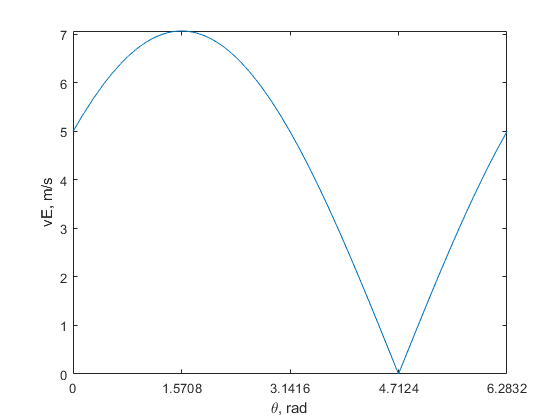

fplot(vEmag,[0,2*pi])
xlabel('\theta, rad')
ylabel('vE, m/s')
set(gca,'XTick',0:pi/2:2*pi)